# PubChem_SMARTS

Search for chemical structures in PubChem via a SMARTS substructure query and compile results

% Vincent F. Scalfani, Serena C. Ralph, and Jason E. Bara 
% The University of Alabama
% Version: 1.0, created with MATLAB R2018a


## Define the PubChem API base URL

% PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';

% set MATLAB web options to a 30 second timeout
options = weboptions('Timeout', 30);

## Define SMARTS queries

% view pattern syntax at: https://smartsview.zbh.uni-hamburg.de/

SMARTSq = {'C1(C(N1~[CX3]([NX3])=[OX1])[CR0])[CR0]','C1(C(N1~[CX3](=O)[OX2H1])[CR0])[CR0]',...
    'C1(C(N1~[CX3](=[OX1])[F,Cl,Br,I])[CR0])[CR0]'}

SMARTSq = 1×3 cell array
    {'C1(C(N1~[CX3]([NX3])=[OX1])[CR0])[CR0]'}    {'C1(C(N1~[CX3](=O)[OX2H1])[CR0])[CR0]'}    {'C1(C(N1~[CX3](=[OX1])[F,Cl,Br,I])[CR0])[CR0]'}


*Add your own SMARTS queries to customize. You can add as many as desired within a cell array.*

## Perform a SMARTS query Search

% generate URLs for SMARTS query searches
for h = 1:length(SMARTSq)
    
    SMARTSq_url{h} = [api 'fastsubstructure/smarts/' char(SMARTSq(h)) '/cids/JSON'];
end

% perform substructure searches for each query link in SMARTSq_url
for i = 1:length(SMARTSq_url)
    
    try
       hit_CIDs{i} = webread(char(SMARTSq_url(i)),options);
        
     % be nice to PubChem Server, add a 1 second pause
       n = 1;
       pause(n)
        
    catch ME
        disp('not found')
    end
    
end

% Transfer JSON data to a cell array with all CIDs
% may need to adjust concatenation below depending on # of SMARTS
hit_CIDsALL = [hit_CIDs{1,1}.IdentifierList.CID; hit_CIDs{1,2}.IdentifierList.CID;...
    hit_CIDs{1,3}.IdentifierList.CID];
hit_CIDsALL = num2cell(hit_CIDsALL)

hit_CIDsALL = 48×1 cell array
    {[ 54118938]}
    {[ 21161981]}
    {[   285042]}
    {[126517619]}
    {[123991601]}
    {[123984797]}
    {[123758413]}
    {[123631400]}
    {[123299308]}
    {[118944493]}
    {[ 90716889]}
    {[   243869]}
    {[   243868]}
    {[   243863]}
    {[  6421387]}
    {[ 11122882]}
    {[ 21768248]}
    {[ 21768249]}
    {[ 21768250]}
    {[ 53785080]}
    {[ 92229480]}
    {[ 92229481]}
    {[ 92229486]}
    {[ 92229487]}
    {[ 92229488]}
    {[ 92229489]}
    {[ 92532732]}
    {[ 92532734]}
    {[ 92532735]}
    {[101579368]}
    {[101579372]}
    {[101579373]}
    {[102330888]}
    {[102330889]}
    {[102330890]}
    {[102331698]}
    {[131876646]}
    {[118484835]}
    {[ 87794850]}
    {[ 87794419]}
    {[ 87794849]}
    {[ 87794966]}
    {[101095940]}
    {[101095942]}
    {[ 12547265]}
    {[ 12547266]}
    {[ 12547272]}
    {[131858483]}


% set a CID limit to 100 max

*The CID limit of 100 was added as an initial testing safety for time consideration. This limit can be increased.*

number_hit_CIDsALL = length(hit_CIDsALL)

number_hit_CIDsALL = 48

if number_hit_CIDsALL > 100
        
        hit_CIDsALL = hit_CIDsALL(1:100)      
else
    disp('Number of CIDs not changed')    
end

Number of CIDs not changed


## Retrieve Identifier and Property Data

% Create an identifier/property dataset from SMARTS Substructure Search results
% Retrieve the following data from CID hit results:
% InChI, Canonical SMILES, MW, HBond Donor Count, HBond Acceptor Count, XLogP

% setup a for loop that processes each CID one-by-one
for r = 1:length(hit_CIDsALL)
    CID = hit_CIDsALL{r};
    
    % define api calls
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_InChI_url = [api 'cid/' num2str(CID) '/property/InChI/TXT'];
    CID_CanSMI_url = [api 'cid/' num2str(CID) '/property/CanonicalSMILES/TXT'];
    CID_MW_url = [api 'cid/' num2str(CID) '/property/MolecularWeight/TXT'];  
    CID_HBond_D_url = [api 'cid/' num2str(CID) '/property/HBondDonorCount/TXT'];
    CID_HBond_A_url = [api 'cid/' num2str(CID) '/property/HBondAcceptorCount/TXT'];
    CID_XLogP_url = [api 'cid/' num2str(CID) '/property/XLogP/TXT'];
        

*Additional property data can be collected by defining new api calls, for example, if you want TPSA data:*

% CID_TPSA_url = [api 'cid/' num2str(CID) '/property/TPSA/TXT'];

    % retrieve identifer and property data
    try
        CID_InChI = webread(CID_InChI_url,options);      
    catch ME
        CID_InChI = 'not found'
    end
        % be polite to PubChem server
        n = 0.5;
        pause(n)
     
    try
        CID_CanSMI = webread(CID_CanSMI_url,options);     
    catch ME  
        CID_CanSMI = 'not found'
    end
        n = 0.5;
        pause(n)
    
    try
        CID_MW = webread(CID_MW_url,options);
    catch ME
        CID_MW = 'not found'
    end    
        n = 0.5;
        pause(n)
            
    try
        CID_HBond_D = webread(CID_HBond_D_url,options);
    catch ME
        CID_HBond_D = 'not found'
    end
        n = 0.5;
        pause(n)
        
    try
        CID_HBond_A = webread(CID_HBond_A_url,options);
    catch ME
        CID_HBond_A = 'not found'
    end
        n = 0.5;
        pause(n)
       
    try
        CID_XLogP = webread(CID_XLogP_url,options);
    catch ME
        CID_XLogP = 'not found'
    end
        n = 0.5;
        pause(n)
        
      % add property data to hit_CIDsALL data array
      
      % column numbers indicate where the data will be stored.
      % For example, the MW will be placed in column 4. r increases
      % by 1 on each iteration, so the first CID_MW value gets stored in
      % {1,4}, the second in {2,4}, the third in {3,4}, etc.
      
        hit_CIDsALL{r,2} = CID_InChI;
        hit_CIDsALL{r,3} = CID_CanSMI;
        hit_CIDsALL{r,4} = CID_MW;
        hit_CIDsALL{r,5} = CID_HBond_D;
        hit_CIDsALL{r,6} = CID_HBond_A;
        hit_CIDsALL{r,7} = CID_XLogP;
        
        
       % to add more data, simply index into the next column
       % hit_CIDsALL{r,8} = CID_TPSA;
                                       
end


## Compile Data into a Table

% convert cell array to string and remove leading and trailing white space
hit_CIDsALLstring = strtrim(string(hit_CIDsALL));

% convert to table
SMARTSq_table = array2table(hit_CIDsALLstring, 'VariableNames',{'CID', 'InChI','CanSMI','MW',...
    'HBond_D','HBond_A','XLogP'})

SMARTSq_table = 48×7 table
        CID                                                                                                                    InChI                                                                                                                                                              CanSMI                                                      MW         HBond_D    HBond_A     XLogP 
    ___________    ______________________________________________________________________________________________________________________________________________________________________________________________________________________________    ________________________________________________________________________________________________    ____________    _______    

% rearrange table so that Canonical SMILES are in column 1
SMARTSq_table2 = SMARTSq_table(:, {'CanSMI' 'CID' 'InChI' 'MW' 'HBond_D' 'HBond_A' 'XLogP'})

SMARTSq_table2 = 48×7 table
                                                 CanSMI                                                     CID                                                                                                                    InChI                                                                                                                      MW         HBond_D    HBond_A     XLogP 
    ________________________________________________________________________________________________    ___________    ______________________________________________________________________________________________________________________________________________________________________________________________________________________________    ____________    _______    

% data export as tabbed text file
% prompt user to select folder for data export
save_folder = uigetdir;

% change directory to selected folder
cd(save_folder)

writetable(SMARTSq_table2,'MATLAB_SMARTSq_results.txt','Delimiter','tab')


## Retrieve Images of CID Compounds from SMARTS query match

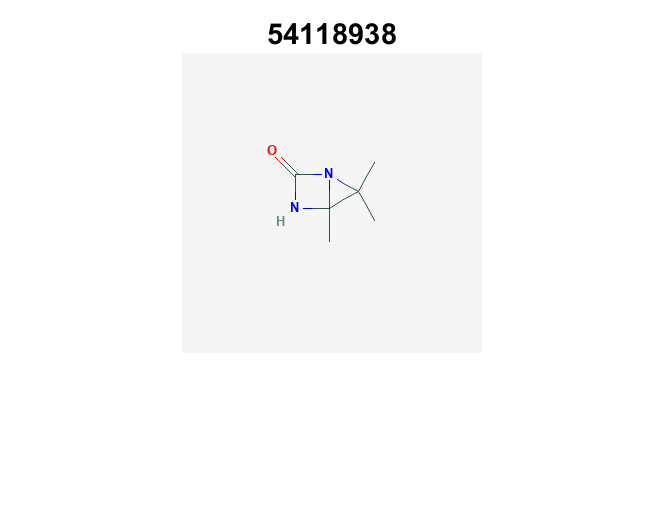

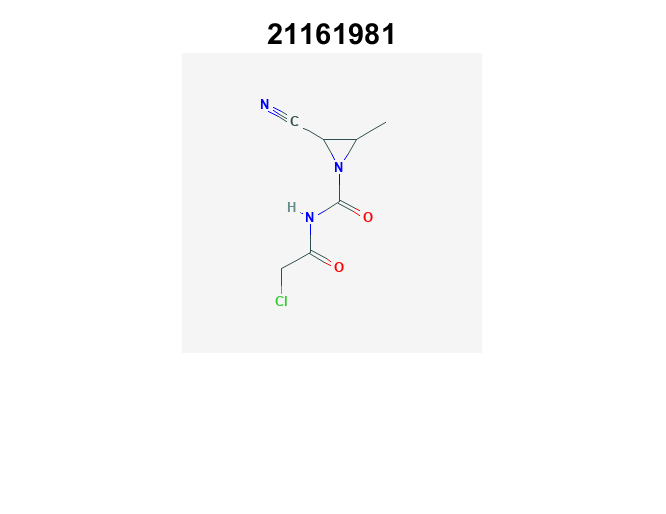

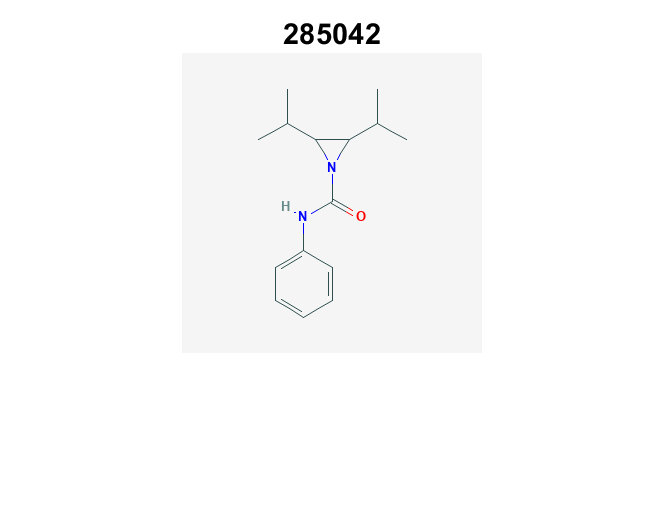

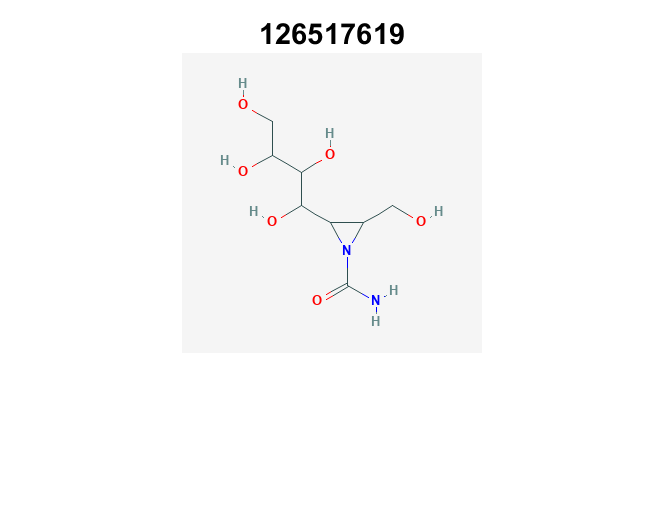

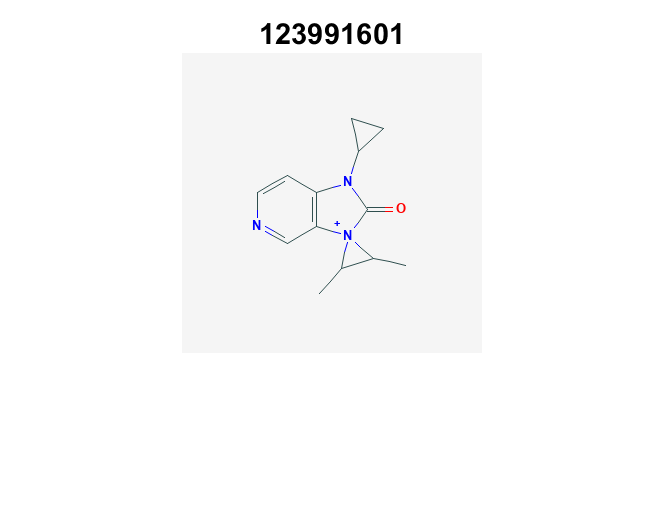

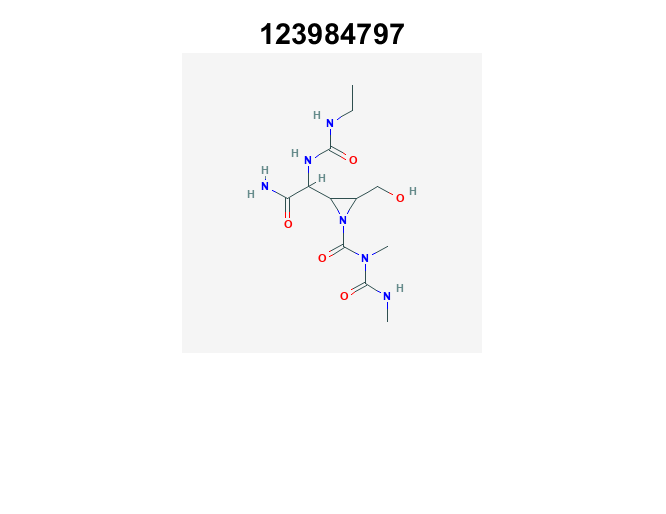

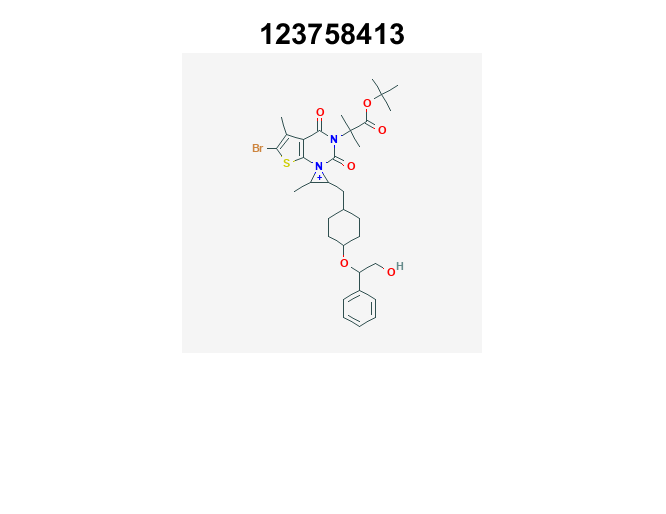

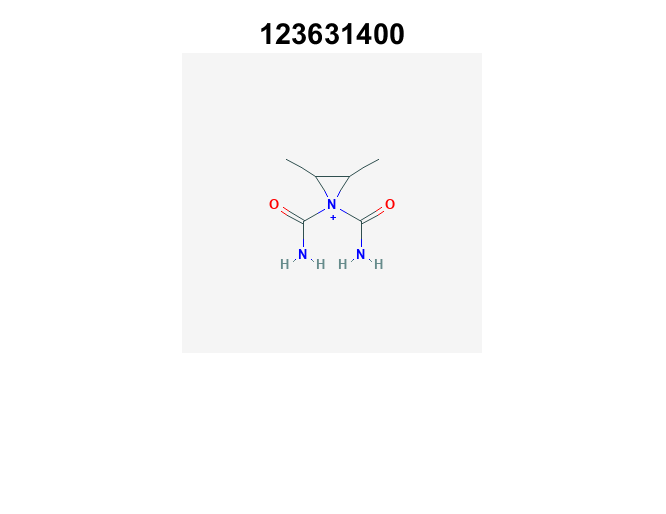

% loop through hit CIDs and show images
for r = 1:length(hit_CIDsALL)
    CID = hit_CIDsALL{r};
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_url = [api 'cid/' num2str(CID) '/PNG'];
    
    try
        % retrieve CID PNG image and display
        [CID_img,map] = imread(CID_url);
        figure;
        imshow(CID_img,map)
        drawnow;
        title(num2str(CID));
        
        % be polite to PubChem server
        n = 0.5;
        pause(n);
        
    catch
        disp('CID image not found')
        disp('Execution will continue')
    end
    
end